# Performance report

### Findings so far

- `pagemtimes` is incredibly fast. It halves the time spent in `LHSintegrator_StiffnessElastic`, literally.

- It looks like the **old** method of assembly is **faster** than the new one. That is, assembling B and C, and multiplying them afterwards, is faster than performing the multiplication at the elemental level and then assembling the final result.

### On the assembly

So, what exactly is slowing down the new method? Well, there are several reasons that come into play, and it is quite difficult to determine exactly how much each of those is affecting the end result.

- **Calculation of dofsInElem**: after moving it inside the `Assembler`, it now has to do the calculation as part of the assembly. The cost in time of this function is often enough to make the new method be slower than the old one.

- **Sparse**: I don't think we are using the `sparse` function to its full potential, since we are still adding sparse matrices in each loop. It is way better to store indices and values, and then create the sparse matrix with the final indices and values obtained. I have quickly implemented a slow version of this, and it is now often faster than the previous method.

- **Sparse (II):** using a slightly better implementation, the results are way better. The assembly is performed much faster (often a whole order of magnitude), except for the 2d_quad test, which is just a tad slower.

- **Yeah, but...** These factors also come into play in the old method — to a lesser extent. The sparse method is called fewer times, and the same is true for the dof connectivity function.

*Side comment: *`DiffReactProblem.createIntegratorParams()`* is quite the mess...*

### Way forward?

So, both methods can be sped up. It is difficult to determine how much, though, and whether attempting to speed up a process will affect another.

- **Elemental product + assembly:** it may be possible to store the indices directly in the elemental matrix so that the assembly is much faster. However, it is possible that then the `pagemtimes` function cannot be used, and thus any gains are lost. Nonetheless, it is certain that the current implementation of the index calculation in the `Assembler` can be sped up.

- **Elemental assembly + product:** the learnings on how to speed the `sparse` function can be implemented here as well. No obvious losses seem to be there.

### Scaled results

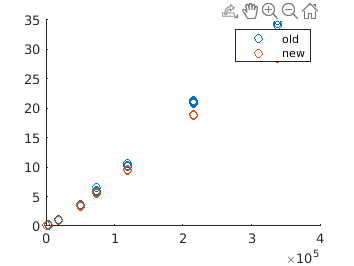

load('resultsNew.mat')
load('resultsOld.mat')
I = ones(1,5);
elems  = [1000*I, 4000*I, 18000*I, 50000*I, 74000*I, 119000*I, 216000*I, 338000*I];
newRes = cell2mat(resultsNew);
oldRes = cell2mat(resultsOld);
scatter(elems, oldRes);
hold on;
scatter(elems, newRes);
legend('old', 'new')